# 'wire_box' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create *povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create *camera* object and put it in separate include file to save rendering time in future

pl.include_begin('camera');
    pl.camera('angle', 35, 'location', [5 24 9], 'look_at', [0 0 -0.6], 'type', 'perspective');
pl.include_end();

#### Create *lights* objects and put them in separate include file to save rendering time in future

pl.include_begin('lights');
    pl.light('location', [10 10 7],     'color', [3 3 3], 'shadowless', true);
    pl.light('location', [-10 10 30],   'color', [3 3 3], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
pl.include_end();

#### Create environment objects and put them in separate include file to save rendering time in future

pl.include_begin('environment');
    % Sky
    pl.raw(['sky_sphere{ pigment{ gradient <0,0,1> '...
                      'color_map{ [0   color rgb<0.0,0.0, 0.0> ] '...
                                 '[0.4 color rgb<0.01, 0.01, 0.01>   ] '...
                                 '[0.8 color rgb<0.03, 0.03, 0.03>   ]  '...
                                 '[1.0 color rgb<0.05, 0.05, 0.05>     ]} '...
                      'scale 1  }}']);
pl.include_end();


#### Scene

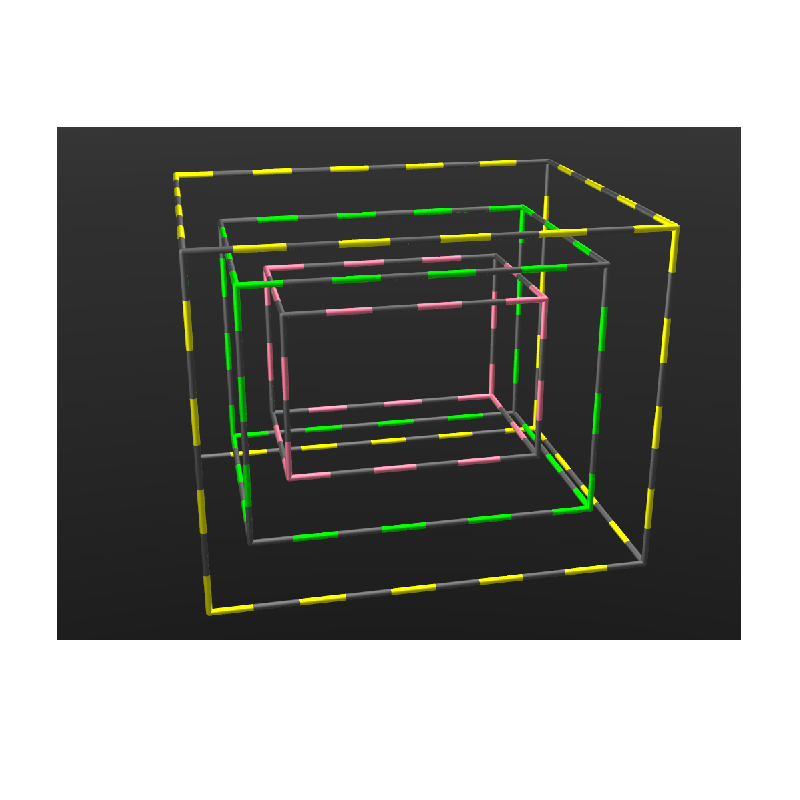

pl.scene_begin('scene_file', 'wire_box.pov', 'image_file', 'wire_box.png');
    pl.include("shapes");
    pl.include("camera");
    pl.include("lights");
    pl.include("environment");

    tex_pink   = pl.declare("tex_plane_pink",   pl.texture('base', 'Silver1', 'pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.8 0.2 0.3], 'finish', "phong 1 reflection {0.3 metallic 0.8}"));
    tex_yellow = pl.declare("tex_plane_yellow", pl.texture('base', 'Silver1', 'pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.8 0.8 0],   'finish', "phong 1 reflection {0.3 metallic 0.8}"));
    tex_green =  pl.declare("tex_green",        pl.texture('base', 'Silver1', 'pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.0 0.8 0],   'finish', "phong 1 reflection {0.3 metallic 0.8}"));

    pl.wire_box('llf_corner', [-5 -4 -4], 'urb_corner', [5 4 4], 'radius', 0.07, 'texture', tex_yellow);
    pl.wire_box('llf_corner', [-3 -2 -2], 'urb_corner', [3 2 2], 'radius', 0.07, 'texture', tex_pink);
    pl.wire_box('llf_corner', [-4 -3 -3], 'urb_corner', [4 3 3], 'radius', 0.07, 'texture', tex_green);

pl.scene_end();

image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 2.449425 seconds.
